# AI621 A4 : HDR Imaging & Tonemapping

20215584 Wonjoon Chang

Youtube: [https://youtu.be/TnPvvUt_sHQ](https://youtu.be/TnPvvUt_sHQ)

## HDR Imaging

dc = readraw;

readraw: installed ReadRaw as loader for RAW camera images.


Load the RAW .NERF images and convert the images into linear 16-bit.

- -w : white balancing

- -T -6 : .TIFF, 16-bit

- -q 3 : high-quality interpolation

- -o 1 : sRGB color space

ims_raw = cell([16,1]);

for i=1:16
    filename = strcat('./data/exposure_stack/exposure',int2str(i),'.nef');
    ims_raw{i} = im2double(imread(dc, filename, '-w -T -6 -q 3 -o 1'));
end

Load the rendered images.

ims = cell([16,1]);

for i=1:16
    filename = strcat('./data/exposure_stack/exposure',int2str(i),'.jpg');
    ims{i} = imread(filename);
end

shutter speed information

t = log(pow2((1:16)-12)); % log t^k

## Linearize Rendered Images

In the camera, the sequence of image processing operations applied to convert a RAW image into a conventional image. This rendered image is non-linear and 8-bit. To undo the non-linearity, we need to estimate the response curve from the exposure stack. We can recover the discrete inverse response function g by solving the following least square optimization problem.

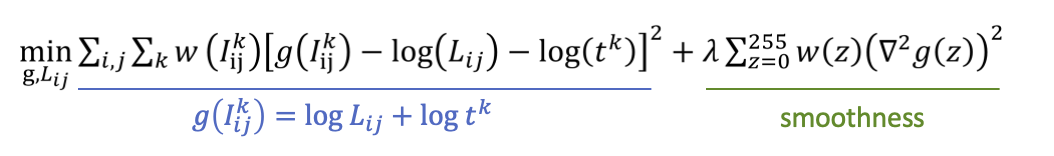

gsolve(Z,B,l,w)

- Z : pixel intensity values

- B : shutter speed ( log t^k )

- l : lambda

- w : weights

Using the whole pixels makes the algorithm heavily costly and actually we only need the sufficient number of pixels to overdetermine the system equation depending on the image size.

totalP = size(ims{1},1)*size(ims{1},2);
P = 300;
tar_pixels = randsample(totalP,P);
N = 16;
l = 150;

Z_rgb = cell([3,1]);
for c=1:3
    Z = zeros(P,N);
    for i=1:N
        Z_tmp = reshape(ims{i}(:,:,c),[totalP,1]);
        Z(:,i) = Z_tmp(tar_pixels);
    end
    Z_rgb{c} = Z;
end

B = zeros(P,N);
for i=1:N
    B(:,i) = t(i);
end

### Weighting Schemes

Select the weighting scheme.

ws = 'uniform';
% ws = 'gaussian';
ws

ws = 'uniform'

if strcmp(ws,'uniform')
    w = ones([256,1]); % uniform
end 
if strcmp(ws,'gaussian')
    w = normpdf((0:255)/255,0.5,0.2); % gaussian
end

[g_r,lE_r] = gsolve(Z_rgb{1},B,l,w);
[g_g,lE_g] = gsolve(Z_rgb{2},B,l,w);
[g_b,lE_b] = gsolve(Z_rgb{3},B,l,w);

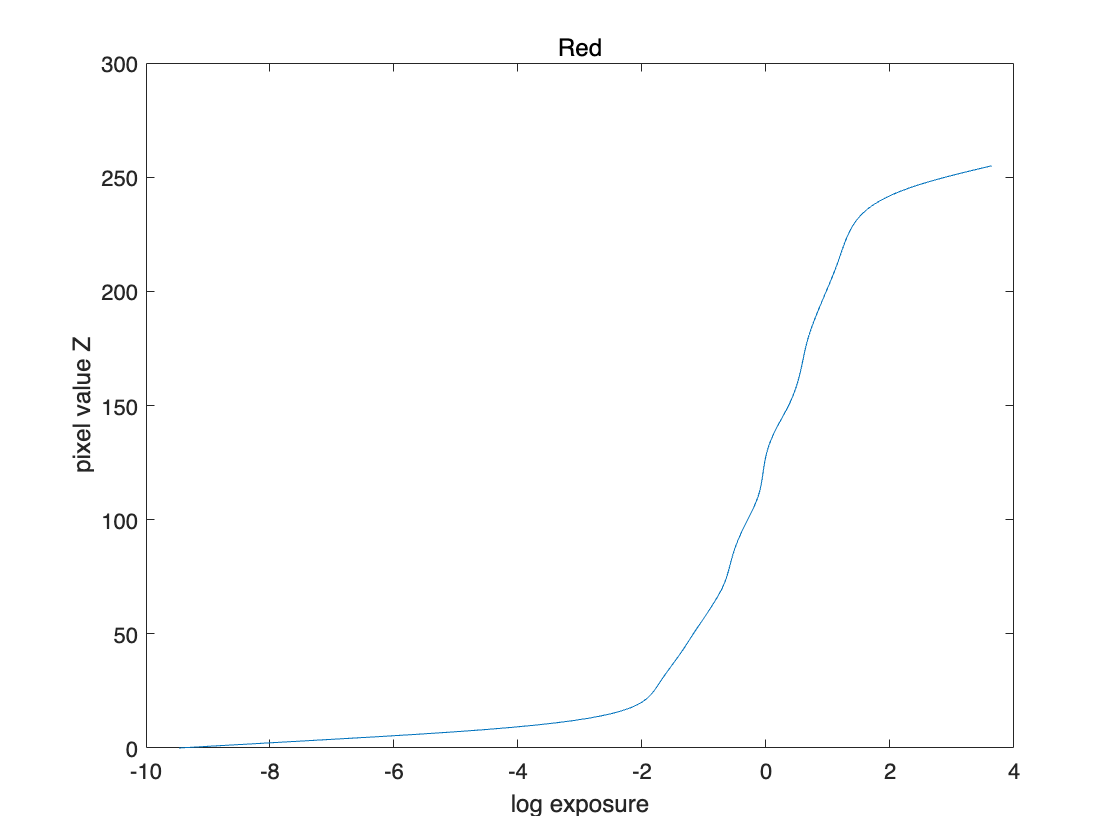

figure;
plot(g_r, 0:255)
title('Red')
xlabel('log exposure')
ylabel('pixel value Z')

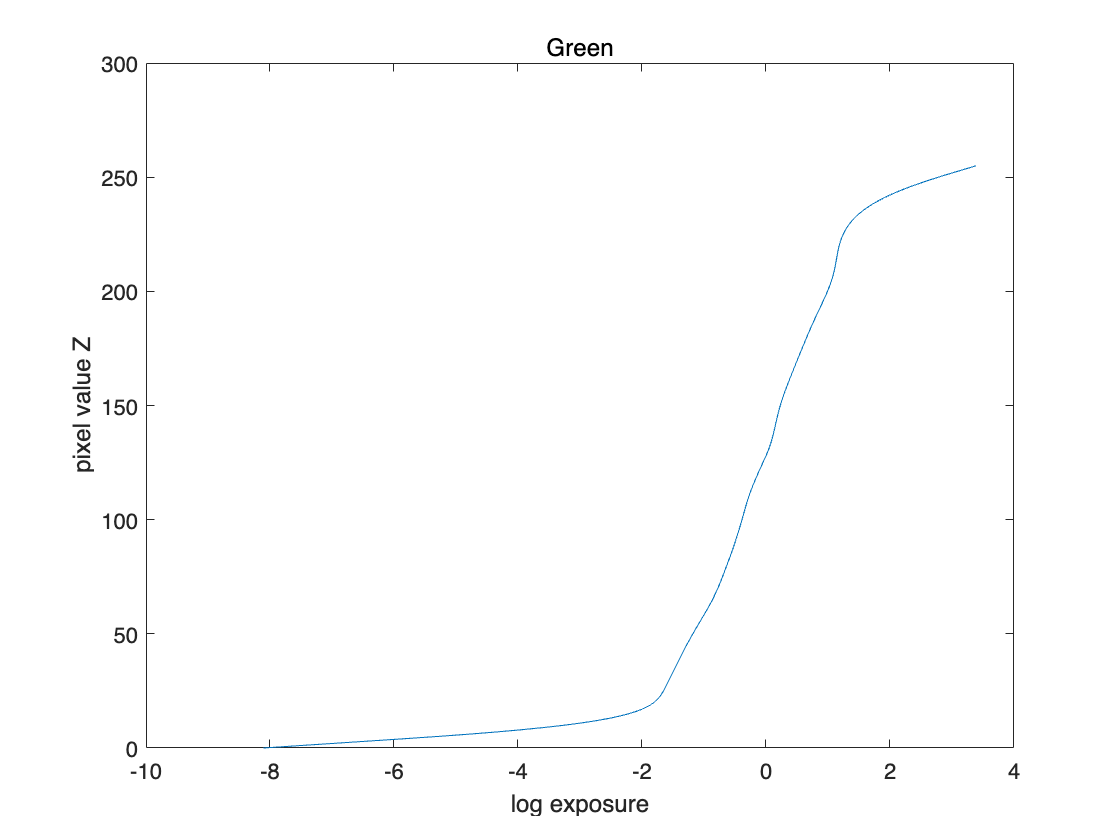

figure;
plot(g_g, 0:255)
title('Green')
xlabel('log exposure')
ylabel('pixel value Z')

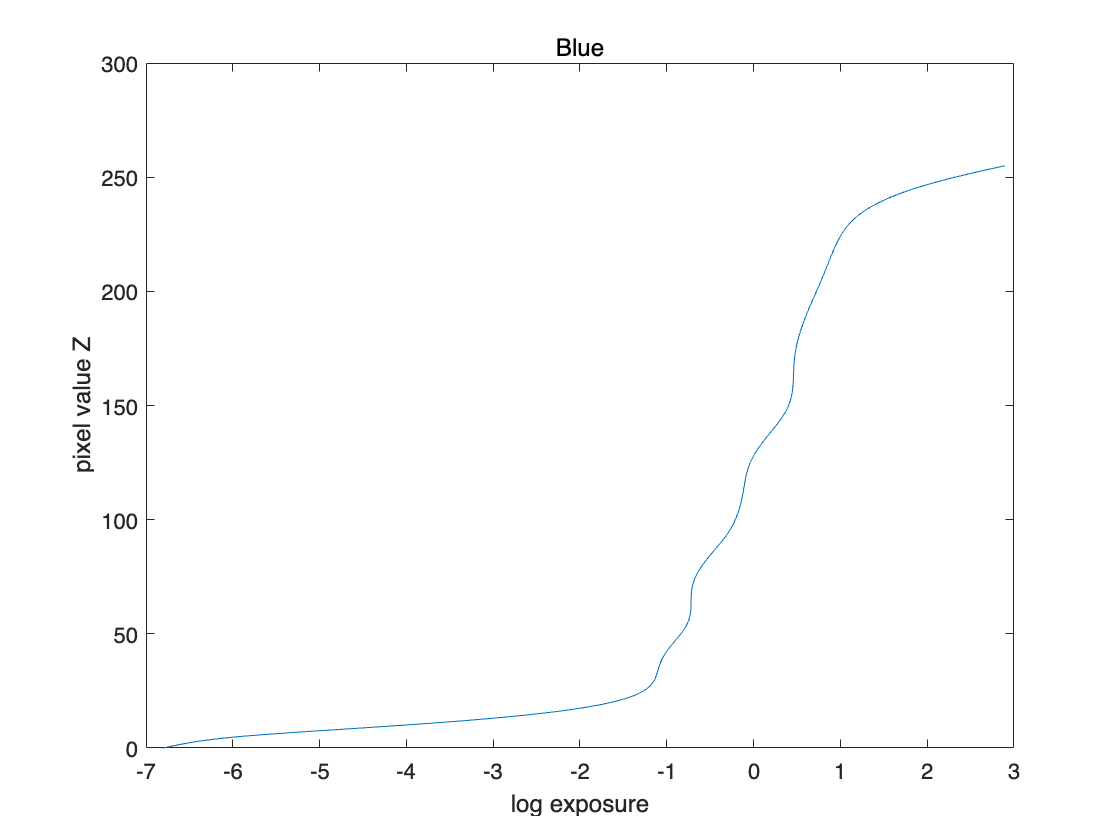

figure;
plot(g_b, 0:255)
title('Blue')
xlabel('log exposure')
ylabel('pixel value Z')

With Gaussian weighting scheme, the response curve seems more natural since it assigns low weighs to over or under-exposed pixels.

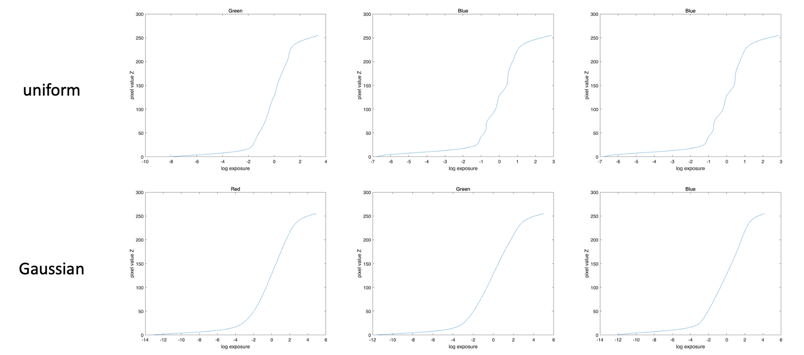

## Merging Exposure Stack into HDR image

There are two merging methods:

- linear merging is motivated by physical accuracy.

- lograithmic merging is motivated by human perception.

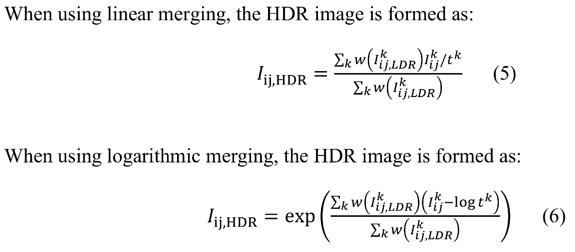

img_type = 'JPG';
% img_type = 'RAW';


if strcmp(img_type,'JPG')
    % rendered images
    disp(img_type)
    ims_lin = cell([16,1]);
    
    for i=1:16
        lin_r = g_r(ims{i}(:,:,1)+1);
        lin_g = g_g(ims{i}(:,:,2)+1);
        lin_b = g_b(ims{i}(:,:,3)+1);
        ims_lin{i} = cat(3,lin_r,lin_g,lin_b);
    end

    for i=1:16
        filename = strcat('./data/exposure_stack/exposure',int2str(i),'.jpg');
        ims{i} = im2double(imread(filename))/255;
    end
end 

JPG


if strcmp(img_type,'RAW')
    %  RAW images
    disp(img_type)
    ims_lin = cell([16,1]);
    
    for i=1:16
        lin_r = log(ims_raw{i}(:,:,1));
        lin_g = log(ims_raw{i}(:,:,2));
        lin_b = log(ims_raw{i}(:,:,3));
        ims_lin{i} = cat(3,lin_r,lin_g,lin_b);
    end
end

### linear merge

if strcmp(img_type,'JPG')
    hdr_lin = lin_merge(ws, ims, ims_lin, t);
end
if strcmp(img_type,'RAW')
    hdr_lin = lin_merge(ws, ims_raw, ims_lin, t);
end

hdrwrite(hdr_lin, './result/rendered_uniform_lin.hdr');

### logarithmic merge

if strcmp(img_type,'JPG')
    hdr_log = log_merge(ws, ims, ims_lin, t);
end

Uniform weighting scheme...


if strcmp(img_type,'RAW')
    hdr_log = log_merge(ws, ims_raw, ims_lin, t);
end

hdrwrite(hdr_log, './result/rendered_uniform_log.hdr');

## Evaluation

One way to evaluate the results of an HDR creation is to check its linearity by using the color checker.

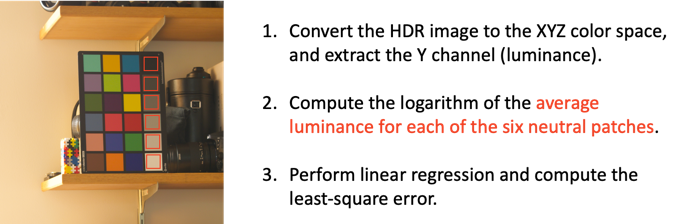

imshow(ims_raw{16})

[xs, ys] = ginput(24);

patches = cell([6,1]);
for p=1:6
    i = 4*(p-1)+1;
    x1 = round(max(xs(i),xs(i+1)));
    x2 = round(min(xs(i+2),xs(i+3)));
    y1 = round(max(ys(i),ys(i+3)));
    y2 = round(min(ys(i+1),ys(i+2)));
    patches{p} = [x1,x2,y1,y2];
end
patches

hdr_file = './result/rendered_uniform_log.hdr';
hdr = hdrread(hdr_file);

XYZ = rgb2xyz(hdr, 'ColorSpace', 'linear-rgb');
lum = XYZ(:,:,2);
avg_log_lum = zeros([6,1]);
for p=1:6
    patch = patches{p};
    avg_log_lum(p) = mean(log(lum(patch(3):patch(4),patch(1):patch(2))+1e-10),'all');
end
avg_log_lum
mdl = fitlm((1:6),avg_log_lum);
error = mdl.RMSE;
plot(mdl)
title(strcat("Error: "+num2str(error)))

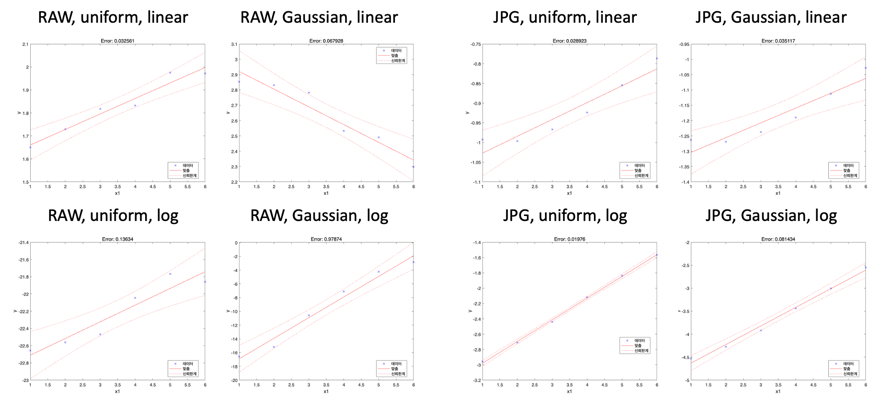

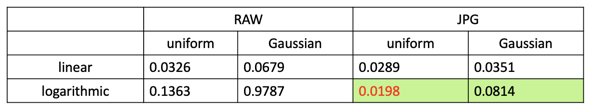

Considering both the qualitative result and the error, I chose to use this HDR image (JPG, uniform, logarithmic merging) in the tonemapping step.